# Tarea 1

## Ejercicio 1:

a) El sistema de ecuaciones lineales asociado al problema de encontrar el polinomio de grado menor o igual que 2 que mejor ajusta por cuadrados mínimos los datos en la tabla 1.1 es el siguiente


$$\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
1 & 1 & 1\\
1 & 2 & 4\\
1 & 3 & 9\\
1 & 4 & 16\\
1 & 5 & 25\\
1 & 6 & 36\\
1 & 7 & 49\\
1 & 8 & 64
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
c_0 \\
c_1 \\
c_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
12\\
10\ldotp 5\\
10\\
8\\
7\\
8\\
7\ldotp 5\\
8\ldotp 5\\
9
\end{array}\right\rbrack$$


b) 

Para construir la matriz **A** y la parte derecha **y** del sistema anterior hacemos uso de las siguientes lineas de código

A =[1 0 0^2; 1 1 1^2; 1 2 2^2; 1 3 3^2; 1 4 4^2; 1 5 5^2; 1 6 6^2; 1 7 7^2; 1 8 8^2];
y = [12 10.5 10 8 7 8 7.5 8.5 9]';

Para resolver el sistema **Ac=y** en el sentido de los mínimos cuadrados hacemos uso de las siguientes lineas de código

c = A\y

c =    12.1848
   -1.8465
    0.1829


Para poder gráficar en un mismo gráfico los pares en la tabla y el polinomio obtenido necesitamos reordenas las entradas del vector **c** obtenido de tal manera que podamos usar el comando *polyval*. Para esto hacemos uso de una matriz de permutación tal como se muestra en el siguiente código

c1 = [0 0 1; 0 1 0; 1 0 0] * c

c1 =     0.1829
   -1.8465
   12.1848


Una vez reordenado el vector **c** podemos generar la gráfica con el siguiente código

x = 0:1:8;
x = x';

z = linspace(0,8,100);
r = polyval(c1,z)

r =    12.1848   12.0368   11.8912   11.7480   11.6071   11.4686   11.3326   11.1989   11.0676   10.9387   10.8121   10.6880   10.5663   10.4469   10.3299   10.2153   10.1032    9.9934    9.8859    9.7809    9.6783    9.5780    9.4802    9.3847    9.2916    9.2009    9.1126    9.0267    8.9432    8.8620    8.7833    8.7069    8.6330    8.5614    8.4922    8.4254    8.3610    8.2989    8.2393    8.1820    8.1272    8.0747    8.0246    7.9769    7.9316    7.8887    7.8482    7.8100    7.7743    7.7409


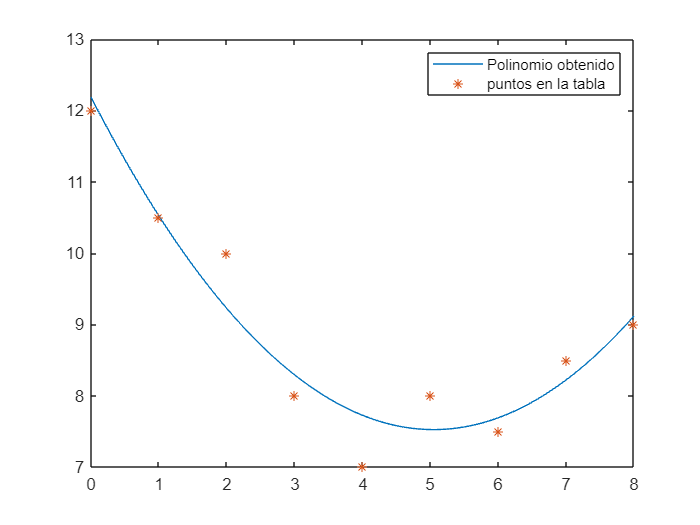


plot(z,r)

hold on

plot(x,y,"*")
legend("Polinomio obtenido","puntos en la tabla")

hold off

Basandonos en el polinomio resultante $p\left(x\right)=12\ldotp 1848-1\ldotp 8465x+0\ldotp 1829x^2$ sabemos que la cantidad de aditivo que resulta en tiempo mínimo de secado sucede cuando $p^{\prime } \left(x^* \right)=0$ ya que ese punto crítico es un mínimo al ser una parabola que abre hacia arriba.

Observemos que $p^{\prime } \left(x\right)=-1\ldotp 8465+0\ldotp 3658x$ y así $p^{\prime } \left(x^* \right)=0$ cuando $x^* =5\ldotp 04784$ gramos. Es decir, que 5.04784 gramos de aditivo resultan en tiempo mínimo de secado basandonos en el polinomio obtenido.

Por otra parte, el tiempo mínimo de secado es $p\left(x^* \right)=p\left(5\ldotp 04784\right)=7\ldotp 52438$ horas.

## Ejercicio 3:

a) Realizando el proceso de linealización para el primer modelo $y_a \left(x\right)=\alpha \beta^x$ tenemos que el sistema asociado es el siguiente


$$\left\lbrack \begin{array}{cc}
1 & 1\\
1 & 2\\
1 & 5\\
1 & 15\\
1 & 25\\
1 & 30\\
1 & 35\\
1 & 40
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ln \left(\alpha \right)\\
\ln \left(\beta \right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\ln \left(99\right)\\
\ln \left(95\right)\\
\ln \left(85\right)\\
\ln \left(55\right)\\
\ln \left(30\right)\\
\ln \left(24\right)\\
\ln \left(20\right)\\
\ln \left(15\right)
\end{array}\right\rbrack$$


Por otra parte, si linealizamos el segundo modelo $y_b \left(x\right)=\alpha \left(100-x\right){10}^{\beta x}$ tenemos que $\ln \left(y_b \left(x\right)\right)=\ln \left(\alpha \left(100-x\right){10}^{\beta x} \right)=\ln \left(\alpha \right)+\ln \left(100-x\right)+\ln \left(10\right)\beta x$.

De esta forma, tenemos que $\ln \left(y_b \left(x\right)\right)-\ln \left(100-x\right)=\ln \left(\alpha \right)+\ln \left(10\right)\beta x$ y evaluando esta última igualdad en los datos obtenemos el siguiente sistema


$$\left\lbrack \begin{array}{cc}
1 & \ln \left(10\right)\times 1\\
1 & \ln \left(10\right)\times 2\\
1 & \ln \left(10\right)\times 5\\
1 & \ln \left(10\right)\times 15\\
1 & \ln \left(10\right)\times 25\\
1 & \ln \left(10\right)\times 30\\
1 & \ln \left(10\right)\times 35\\
1 & \ln \left(10\right)\times 40
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ln \left(\alpha \right)\\
\beta 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\ln \left(99\right)-\ln \left(99\right)\\
\ln \left(95\right)-\ln \left(98\right)\\
\ln \left(85\right)-\ln \left(95\right)\\
\ln \left(55\right)-\ln \left(85\right)\\
\ln \left(30\right)-\ln \left(75\right)\\
\ln \left(24\right)-\ln \left(70\right)\\
\ln \left(20\right)-\ln \left(65\right)\\
\ln \left(15\right)-\ln \left(60\right)
\end{array}\right\rbrack$$


Para resolver el sistema del primer modelo empleamos el siguiente código

A1 = [1 1; 1 2; 1 5; 1 15; 1 25; 1 30; 1 35; 1 40];
y = [99 95 85 55 30 24 20 15]';
y1 = log(y)

y1 =     4.5951
    4.5539
    4.4427
    4.0073
    3.4012
    3.1781
    2.9957
    2.7081



c1 = A1\y1

c1 =     4.6685
   -0.0488


c1_final = exp(c1)

c1_final =   106.5362
    0.9524


Por lo tanto, se tiene que para el primer modelo $\alpha =106\ldotp 5362$ y $\beta =0\ldotp 9524$.

Para resolver el sistena del segundo modelo empleamos el siguiente código

A2 = [1 log(10); 1 2*log(10); 1 5*log(10); 1 15*log(10); 1 25*log(10); 1 30*log(10); 1 35*log(10); 1 40*log(10)]

A2 =     1.0000    2.3026
    1.0000    4.6052
    1.0000   11.5129
    1.0000   34.5388
    1.0000   57.5646
    1.0000   69.0776
    1.0000   80.5905
    1.0000   92.1034


x = [1 2 5 15 25 30 35 40]';
y = [99 95 85 55 30 24 20 15]';
y2 = log(y) - log(100-x)

y2 =          0
   -0.0311
   -0.1112
   -0.4353
   -0.9163
   -1.0704
   -1.1787
   -1.3863



c2 = A2\y2

c2 =     0.0512
   -0.0157


c2_final = [exp(c2(1)) c2(2)]'

c2_final =     1.0525
   -0.0157


Por lo tanto, se tiene que para el segundo modelo $\alpha =1\ldotp 0525$ y $\beta =-0\ldotp 0157$.

b)

Ahora calculemos la norma del error de ambos modelos usando las siguientes lineas de código

n1 = norm(y1 - A1*c1)

n1 = 0.1024

n2 = norm(y2 - A2*c2)

n2 = 0.1026

De lo anterior, podemos concluir que el primer modelo es el que comete menor error.

c) A continuación mostraremos en un mismo gráfico ambos modelos ajustados

x = [1 2 5 15 25 30 35 40]';
z = linspace(0,40,1000);

r1 = c1_final(1)*(c1_final(2).^z);
r2 = c2_final(1)*(100-z).*(10.^(c2_final(2)*z))

r2 =   105.2490  105.0545  104.8603  104.6665  104.4730  104.2798  104.0870  103.8945  103.7024  103.5106  103.3191  103.1280  102.9372  102.7468  102.5567  102.3669  102.1774  101.9883  101.7995  101.6111  101.4230  101.2352  101.0478  100.8607  100.6739  100.4874  100.3013  100.1155   99.9300   99.7449   99.5600   99.3755   99.1914   99.0075   98.8240   98.6408   98.4580   98.2754   98.0932   97.9113   97.7297   97.5484   97.3675   97.1869   97.0066   96.8266   96.6469   96.4676   96.2885   96.1098


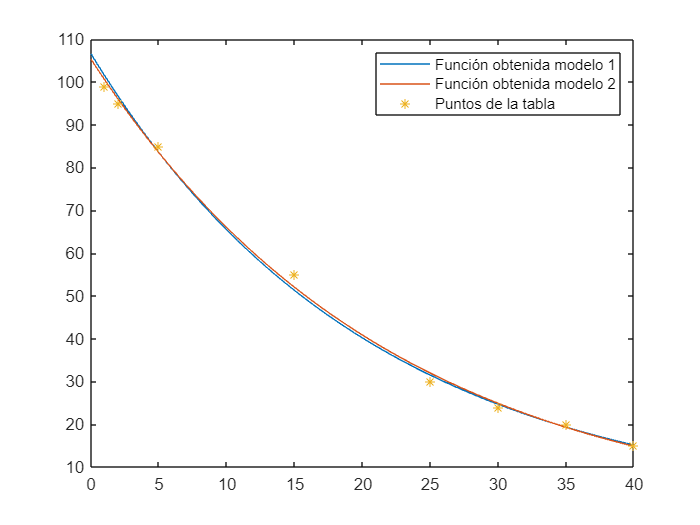


plot(z,r1)

hold on
plot(z,r2)
plot(x,y,"*")
legend("Función obtenida modelo 1","Función obtenida modelo 2","Puntos de la tabla")

hold off

d) Por lo expuesto anteriormente sabemos que el primer modelo $y_a \left(x\right)=\alpha \beta^x$ es mejor al tener menor norma del error. A continuación mostramos la implementación de la función de este modelo (Se puede ver al final del reporte) y el porcentaje de las llantas radiales del fabricante que durarán 45 mil millas y 50 mil millas.

p1=modelo1(45)

p1 = 11.8537

p2=modelo1(50)

p2 = 9.2874

## Ejercicio 5:

a) Sabemos que se cumple la relación entre la concentración de iones y el tiempo

$n=\frac{n_0 }{1+n_0 \alpha t}$ donde $n_0$ es la concentración inicial de iones y $\alpha$ el coeficiente de recombinación.

Notemos que despejando la ecuación anterior tenemos que $1+n_0 \alpha t=n_{0\;} n^{-1}$por lo cual $n^{-1} =\frac{1}{n_0 }+\alpha t$. Es decir, que existe una relación lineal entre $n^{-1}$ y $t$.

Por lo tanto, $n^{-1} ={n_0 }^{-1} +\alpha t$.

b)

Reemplazando los datos en la relación obtenida anteriormente obtenemos el siguiente sistema **Ac=y** el cual resolveremos en el sentido de los minimos cuadrados

A = [1 0; 1 1; 1 2; 1 3; 1 4; 1 5; 1 6; 1 7; 1 8; 1 9; 1 10]

A =      1     0
     1     1
     1     2
     1     3
     1     4
     1     5
     1     6
     1     7
     1     8
     1     9


y = 1./[5.03 4.71 4.40 3.97 3.88 3.62 3.30 3.15 3.08 2.92 2.70]'

y =     0.1988
    0.2123
    0.2273
    0.2519
    0.2577
    0.2762
    0.3030
    0.3175
    0.3247
    0.3425


c = A\y;

c_final = [1/c(1) c(2)]'

c_final =     5.0956
    0.0168


Por lo tanto, la función que mejor ajusta por cuadrados mínimos a los datos de la tabla es $n=\frac{5\ldotp 0956}{1+0\ldotp 0856t}$ donde $n_0 =5\ldotp 0956$ y $\alpha =0\ldotp 0168$

c) Para realizar la gráfica de la función $n$ obtenida y de los pares ordenados en la tabla hacemos uso del siguiente código.

t = [0 1 2 3 4 5 6 7 8 9 10]';
z = linspace(0,10,110);

y1 = [5.03 4.71 4.40 3.97 3.88 3.62 3.30 3.15 3.08 2.92 2.70]'

y1 =     5.0300
    4.7100
    4.4000
    3.9700
    3.8800
    3.6200
    3.3000
    3.1500
    3.0800
    2.9200


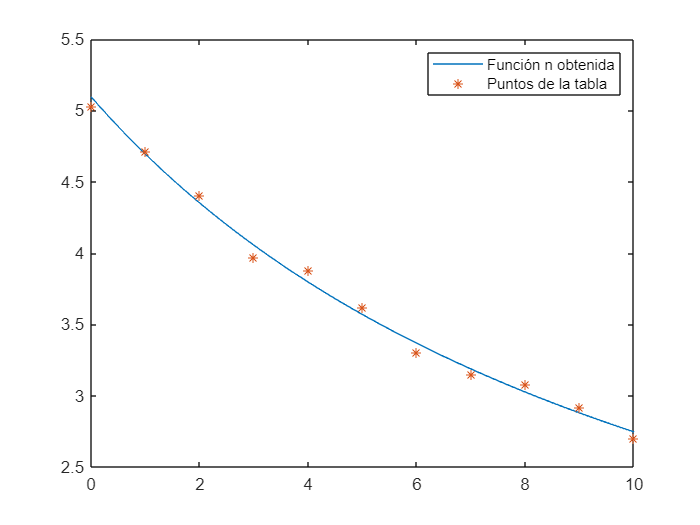


n = c_final(1)./(1+(c_final(1).*c_final(2).*z));

plot(z,n)

hold on
plot(t,y1,"*")
legend("Función n obtenida","Puntos de la tabla")

hold off

function z=modelo1(x)
A1 = [1 1; 1 2; 1 5; 1 15; 1 25; 1 30; 1 35; 1 40];
y = [99 95 85 55 30 24 20 15]';
y1 = log(y);

c1 = A1\y1;
c1_final = exp(c1);
z = c1_final(1)*(c1_final(2).^x);
end